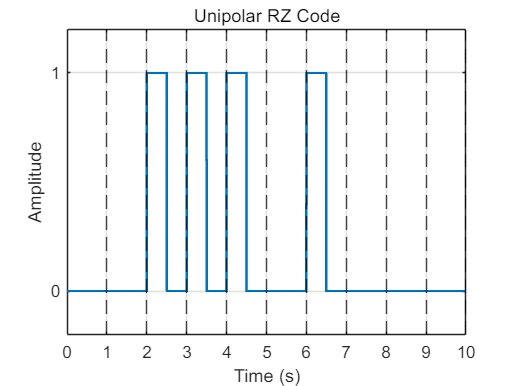

%RZ code generation
% % 输入二进制数据
% binary_data = [1 0 1 1 0 1 0 0 1 1]; 

% 随机生成二进制数据序列
data_length = 10;          % 二进制序列长度
binary_data = randi([0, 1], 1, data_length);  % 随机生成 0 和 1

% 参数设置
bit_duration = 1;  % 每比特的时间长度（秒）
fs = 1000;         % 采样频率（Hz）

% 初始化
t = 0:1/fs:length(binary_data)*bit_duration - 1/fs;  % 时间向量
signal = zeros(size(t));                            % 初始化信号

% 生成单极性归零码
for i = 1:length(binary_data)
    bit_start = (i-1)*bit_duration*fs + 1;               % 当前比特起点
    bit_mid = bit_start + floor(bit_duration*fs/2) - 1;  % 当前比特中点
    if binary_data(i) == 1
        signal(bit_start:bit_mid) = 1;  % 按单极性归零规则设置信号
    end
end

% 画图
figure;
plot(t, signal, 'LineWidth', 1.5);
grid on;
ylim([-0.2, 1.2]);
xlabel('Time (s)');
ylabel('Amplitude');
title('Unipolar RZ Code');
xticks(0:bit_duration:length(binary_data)*bit_duration);
yticks([0 1]);
xline((1:length(binary_data))*bit_duration, '--k'); % 添加虚线分隔每个比特

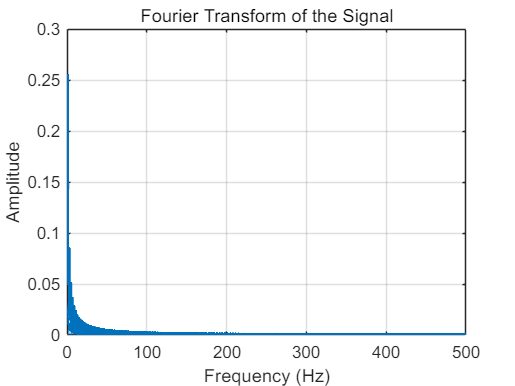


% 调用傅里叶变换函数并画频谱
plotFourierTransform(signal, fs);